clear;
clc;
clf;

%此程序用于生成一个考虑了切趾(这里是等距),无分区的大口径光子筛
t1=clock;
f1=2;%记住单位是m米
D1=0.03;
lamda1=632.8e-9;
k1=2*pi/lamda1;
eta1=1.53;
N1=N(D1,lamda1,f1);%算总环数
number=0;   %计数用
%N1=19041;测试数据
para=zeros([4,N1]);
%创造每一环的参数
%环半径1
%环宽度2
%每一环的孔径数3
%每一环孔径的直径4
for i=1:N1
    epsilon=0.5;%*win_m(i+N1,2*N1);
    para(1,i)=r_m(i,lamda1,f1);
    para(2,i)=w_m(para(1,i),lamda1,f1);
    para(3,i)=N_m(epsilon,eta1,para(1,i),para(2,i));
    para(4,i)=eta1*para(2,i);
    number=number+para(3,i);
end    

save sample1_para para  N1 number
%PMIR=    %用于存放每一个产出的孔径

hole=zeros(3,number,'single');
number1=1;
for i=1:N1
    r_m1=para(1,i);
    w_m1=para(2,i);
    N_m1=para(3,i);
    d=para(4,i);
    for j=0:2*pi/N_m1:2*pi*(N_m1-1)/N_m1
        x=r_m1*cos(j);
        y=r_m1*sin(j);
        hole(:,number1)=[x y d/2];
        number1=number1+1;
    end
end
%hole1=hole(:,1:number1-1);%测试用

save sample1_hole.mat hole

t2=clock;
etime(t2,t1)

ans = 0.0470

%此部分用于生产需要的scr文件
fid=fopen('data_cp11.scr','w');
str0='circle';
for i=1:number 
fprintf(fid,'%s %g,%g %g\r\n',str0,roundn(1000*hole(1,i),-4),roundn(1000*hole(2,i),-4),roundn(1000*hole(3,i),-5));%文件格式按CAD脚本文件要求设置，需要将文件另存为.scr，建议先运行少量数据测试后再整体运行。
%fprintf(fid,'\n');
end
fclose(fid); 

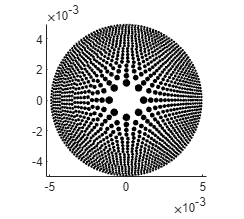

%此节用于生成光子筛展示用图样,只是看看用的

clf
for i=1:number
    rectangle('Position',[hole(1,i)-hole(3,i),hole(2,i)-hole(3,i),hole(3,i)*2,hole(3,i)*2],'FaceColor','k',...
        'EdgeColor','k','Curvature',[1 1])
end    
axis equal 

%此节用于产生光子筛掩模图(加入一个估计时间,孔数要大于1000)
L=1;%L为考察面距
p1=0;
delta=(lamda1*f1/D1)/2;
series=-D1/2:delta:D1/2;
[X,Y]=meshgrid(series,series);%这是实际原坐标取上下对称
t1=clock;
deltat1=0;
deltat2=0;
for i=1:1000
    t3=clock;
    circle=addcircle1(X,Y,hole(1,i),hole(2,i),hole(3,i));
    t4=clock;
    deltat1=deltat1+etime(t4,t3);
    t5=clock;
    p1=p1+circle;
    t6=clock;
    deltat2=deltat2+etime(t6,t5);
    %这个函数得优化一下,感觉大的矩阵计算甚至没有循环单算来得快.
end
t2=clock;
delta_t=etime(t2,t1);

disp(['estimated time ',num2str(number*delta_t/1000),' s'])

estimated time 168.2446 s


pause;
for i=1001:number
    p1=p1+addcircle1(X,Y,hole(1,i),hole(2,i),hole(3,i));
end
t2=clock;
etime(t2,t1)

%此节用于产生光子筛掩模图(加入一个估计时间,孔数要大于1000)
L=1;%L为考察面距
p1=0;
delta=(lamda1*f1/D1)/2;
series=-D1/2:delta:D1/2;
[X,Y]=meshgrid(series,series);%这是实际原坐标取上下对称
t1=clock;
deltat1=0;
deltat2=0;
for i=1:1000
    circle=addcircle1(X,Y,hole(1,i),hole(2,i),hole(3,i));
    p1=p1+circle;
    %这个函数得优化一下,感觉大的矩阵计算甚至没有循环单算来得快.
end
t2=clock;
delta_t=etime(t2,t1);

disp(['estimated time ',num2str(number*delta_t/1000),' s'])

estimated time 164.2296 s


pause;
for i=1001:number
    p1=p1+addcircle1(X,Y,hole(1,i),hole(2,i),hole(3,i));
end
t2=clock;
etime(t2,t1)

%此节用于产生光子筛掩模图(加入一个估计时间,孔数要大于1000,gpu)
L=1;%L为考察面距
p1=0;
delta=(lamda1*f1/D1)/2;
series=-D1/2:delta:D1/2;
[X,Y]=meshgrid(series,series);%这是实际原坐标取上下对称
X=gpuArray(X);
Y=gpuArray(Y);
t1=clock;
deltat1=0;
deltat2=0;
for i=1:1000

    circle=addcircle1(X,Y,hole(1,i),hole(2,i),hole(3,i));



    p1=p1+circle;


    %这个函数得优化一下,感觉大的矩阵计算甚至没有循环单算来得快.
end
t2=clock;
delta_t=etime(t2,t1);

disp(['estimated time ',num2str(number*delta_t/1000),' s'])

estimated time 20.7174 s


pause;
for i=1001:number
    p1=p1+addcircle1(X,Y,hole(1,i),hole(2,i),hole(3,i));
end
t2=clock;
etime(t2,t1)

ans = 15.1170

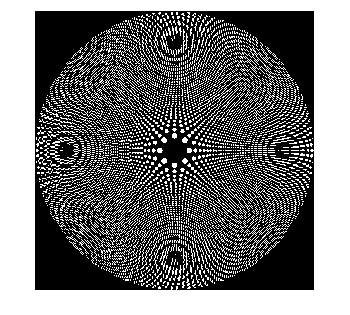

imshow(p1)

save mask.mat p1

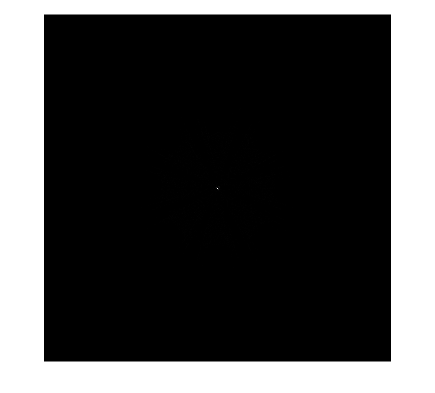

%用于生成衍射图样
t1=clock;
%k1=2*pi/lamda1;
%B=tilt(0,k1,Y);
%B1=B;%测试用
B=FF_propagator(p1,D1,lamda1,f1);
B=B.*conj(B);
B_max=max(max(B));
%imagesc(abs(u2));colormap(hot),colorbar;
imshow(B/B_max*255)

B_max=max(max(B/B_max));
t2=clock;
etime(t2,t1)

ans = 1.7850

function r=r_m(m,lamda,f)   %算环带半径
    r=(m^2*lamda^2+2*m*lamda*f)^0.5;
end

%算环带间隔,明带,自变量明带半径
function w=w_m(R,lamda,f)
    w=lamda*f/(2*R);
end

%算环带数
function n=N(D,lamda,f)
    n=fix(D*D/(8*f*lamda));
end

%按照指定填充因子计算m环孔径数
function N=N_m(epsilon,eta,r_m0,w_m0)
    N=fix(epsilon*2*pi*r_m0/(eta*w_m0));
end

%"大口径光子筛小孔环带设计方法研究_周润"高斯窗等距切趾,0.4是高斯参数
function win1=win_m(n,N)
    win1=exp(-0.5*((n-0.5*(N-1))/(0.5*0.4*(N-1)))^2);
end

%
function out=addcircle1(X,Y,x0,y0,r)
 out=sqrt((X-x0).^2+(Y-y0).^2)<=r;
end

function matrixa=addcirc(A,d,x,y,delta)
%A输入平面,d为孔大小,dlta采样间隔,这是一个特化的函数
a=round(x/delta);
b=round(y/delta);
r=round(d/(2*delta));
n=0;
for i=-r:r
    for j=-r:r
        if (i)^2+(j)^2<r^2 && a+i>-1000 && a+i<1000 && b+j>-1000 && b+j<1000
            A(1000+a+i,1000+b+j)=1;
            n=n+1;
        end
    end
end
matrixa=A;
end

%用来算倾斜的平面波,x,y类型没有要求
function tilt_light=tilt(cita,k,y)
    tilt_light=exp(1i*k*(y*sind(cita)));
end


function u2=TF_propagator(u1,L,lambda,Z)
%k=2*pi/lambda; % 波数
[M,N]=size(u1); % 采样长度
dx=L/M; % 采样间隔
dy=L/N;
fx=-1/(2*dx):1/L: 1/(2*dx)-1/L; % 频率域坐标
fy=-1/(2*dy):1/L: 1/(2*dy)-1/L;
[fX,fY]=meshgrid(fx,fy); % 频率域坐标网格
H=exp(-1i*3.1415923*lambda*Z*(fX.^2+fY.^2)); % 传递函数
H=fftshift(H); % 移位操作
U1=fft2(fftshift(u1)); % 衍射孔径的移位和 FFT
U2=H.*U1; % 相乘
u2=ifftshift(ifft2(U2)); % 考察平面的光场
end

function u2=FF_propagator(u1,L1,lambda,Z)
%FF衍射
[M,N]=size(u1);               % 衍射孔径平面采样长度
dx1=L1/M;                   % 衍射孔径采样间隔
k=2*pi/lambda;               % 波数
L2=lambda*Z/dx1;             % 考察平面采样长度
dx2=lambda*Z/L1;             % 考察平面采样间隔
x2=-L2/2:dx2:L2/2-dx2;         % 考察平面坐标坐标
[X2,Y2]=meshgrid(x2,x2);       % 考察平面坐标网格
A=1/(j*lambda*Z)*exp(j*k/(2*Z)*(X2.^2+Y2.^2));   % 常数
u2=A.*ifftshift(ifft2(fftshift(u1)))*dx1^2;   % 考察平面光场
end